# **Clasificación de movimientos de la mano usando sensor MyoWare y el Classification Learner Toolbox de Matlab**

Estudiantes:

- **Hernán Campos**

- **Jean Mejia**

Características del experimentos:

- 1-Cerrar 2 veces la mano

- 2-Apuntar con el dedo índice

- 3-Símbolo de paz y amor

- 4-Pulgar arriba

- 5-Hacer puño

- 6-Descanso

Características del hardware:

- Frecuencia de muestreo: 100Hz

- Sensor MyoWare

Referencias:

- **Funciones de Matlab: **[**https://github.com/vasanza/Matlab_Code**](https://github.com/vasanza/Matlab_Code)

- **Señales Electromiografícas: **[**https://github.com/vasanza/EMG-Wearable**](https://github.com/vasanza/EMG-Wearable)

Notas para el uso:

- Se recomienda organizar los datos en la carpeta "data" y las funciones en la carpeta "src".

- Para ejecutar el codigo principal "main.mlx", poner el current folder en la misma ubicación.

- **En el siguiente enlace se puede revisar como fue desarrollado el presente codigo:**

- [**https://youtu.be/UI7Oa1sXEeY**](https://youtu.be/UI7Oa1sXEeY)

# 1- Load Raw Data

clear;clc;%Limpiar
addpath(genpath('./src'))%Carpeta de funciones
datapath = fullfile('./data/');%Carpeta de datos
folderNames=FindFolders(datapath);

allDataT1S1=[];
allDataT2S1=[];
allDataT3S1=[];
allDataT4S1=[];
allDataT5S1=[];
allDataT6S1=[];

allDataT1S2=[];
allDataT2S2=[];
allDataT3S2=[];
allDataT4S2=[];
allDataT5S2=[];
allDataT6S2=[];

for j=1:length(folderNames)
    path1=fullfile(datapath,folderNames(j).name);
    filenames = FindCSV(path1);%Listar todos los archivos CSV
    for i=1:length(filenames)%Recorrer todos los archivos CSV
        data=readtable(fullfile(path1,filenames(i).name));%Seleccionar CSV
        dataNew=table2array(data(:,2));
        dataNew(isnan(dataNew)) = 0;%Remover NAN numbers
        Label=str2double(filenames(i).name(2));%Caracter que identifica la tarea
        featureData = [std(dataNew) mean(dataNew)];%Caracteristicas a usar
        if ((filenames(i).name(4) == "1") && (folderNames(j).name(6) == "1"))
            allDataT1S1=[allDataT1S1;[featureData Label]];
        elseif ((filenames(i).name(4) == "1") && (folderNames(j).name(6) == "2"))
            allDataT2S1=[allDataT2S1;[featureData Label]];
        elseif ((filenames(i).name(4) == "1") && (folderNames(j).name(6) == "3"))
            allDataT3S1=[allDataT3S1;[featureData Label]];
        elseif ((filenames(i).name(4) == "1") && (folderNames(j).name(6) == "4"))
            allDataT4S1=[allDataT4S1;[featureData Label]];
        elseif ((filenames(i).name(4) == "1") && (folderNames(j).name(6) == "5"))
            allDataT5S1=[allDataT5S1;[featureData Label]];
        elseif ((filenames(i).name(4) == "1") && (folderNames(j).name(6) == "6"))
            allDataT6S1=[allDataT6S1;[featureData Label]];
        
        elseif ((filenames(i).name(4) == "2") && (folderNames(j).name(6) == "1"))
            allDataT1S2=[allDataT1S2;[featureData Label]];
        elseif ((filenames(i).name(4) == "2") && (folderNames(j).name(6) == "2"))
            allDataT2S2=[allDataT2S2;[featureData Label]];
        elseif ((filenames(i).name(4) == "2") && (folderNames(j).name(6) == "3"))
            allDataT3S2=[allDataT3S2;[featureData Label]];
        elseif ((filenames(i).name(4) == "2") && (folderNames(j).name(6) == "4"))
            allDataT4S2=[allDataT4S2;[featureData Label]];
        elseif ((filenames(i).name(4) == "2") && (folderNames(j).name(6) == "5"))
            allDataT5S2=[allDataT5S2;[featureData Label]];
        elseif ((filenames(i).name(4) == "2") && (folderNames(j).name(6) == "6"))
            allDataT6S2=[allDataT6S2;[featureData Label]];
        end
    end
end

# 2- Grafica de datos

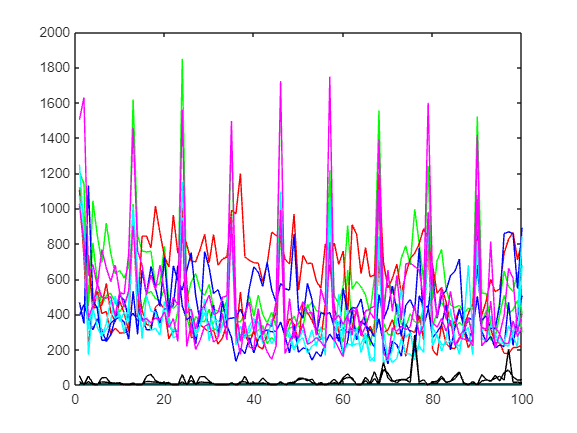

x = 1:100; %Para Graficar
plot(x, allDataT1S1, 'green', x, allDataT2S1, 'red', x, allDataT3S1, 'blue', ...

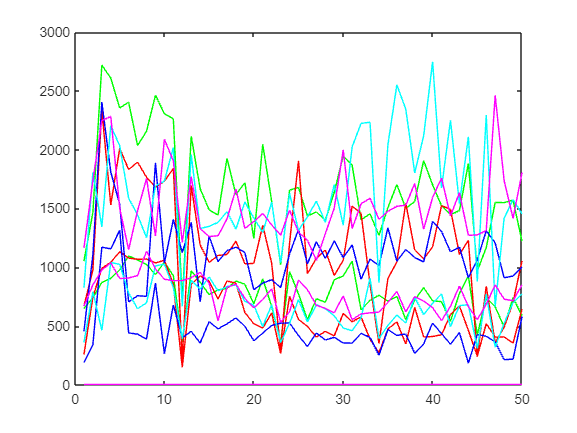

     x, allDataT4S1, 'cyan', x, allDataT5S1, 'magenta', x, allDataT6S1, 'black')
y = 1:50; %Para Graficar
plot(y, allDataT1S2, 'green', y, allDataT2S2, 'red', y, allDataT3S2, 'blue', ...

     y, allDataT4S2, 'cyan', y, allDataT5S2, 'magenta')

# 3- Classification

%Solo se seleccionan los registros clasificables
dataset = [allDataT1S2; allDataT2S1; allDataT3S2; allDataT4S2; allDataT6S1];
[RandomData,IndexRows] = fRandomize_DataRows(dataset);
[Training, Validation] = fsplit_data(RandomData, 0.7);%70% para Training y 30% para Validation

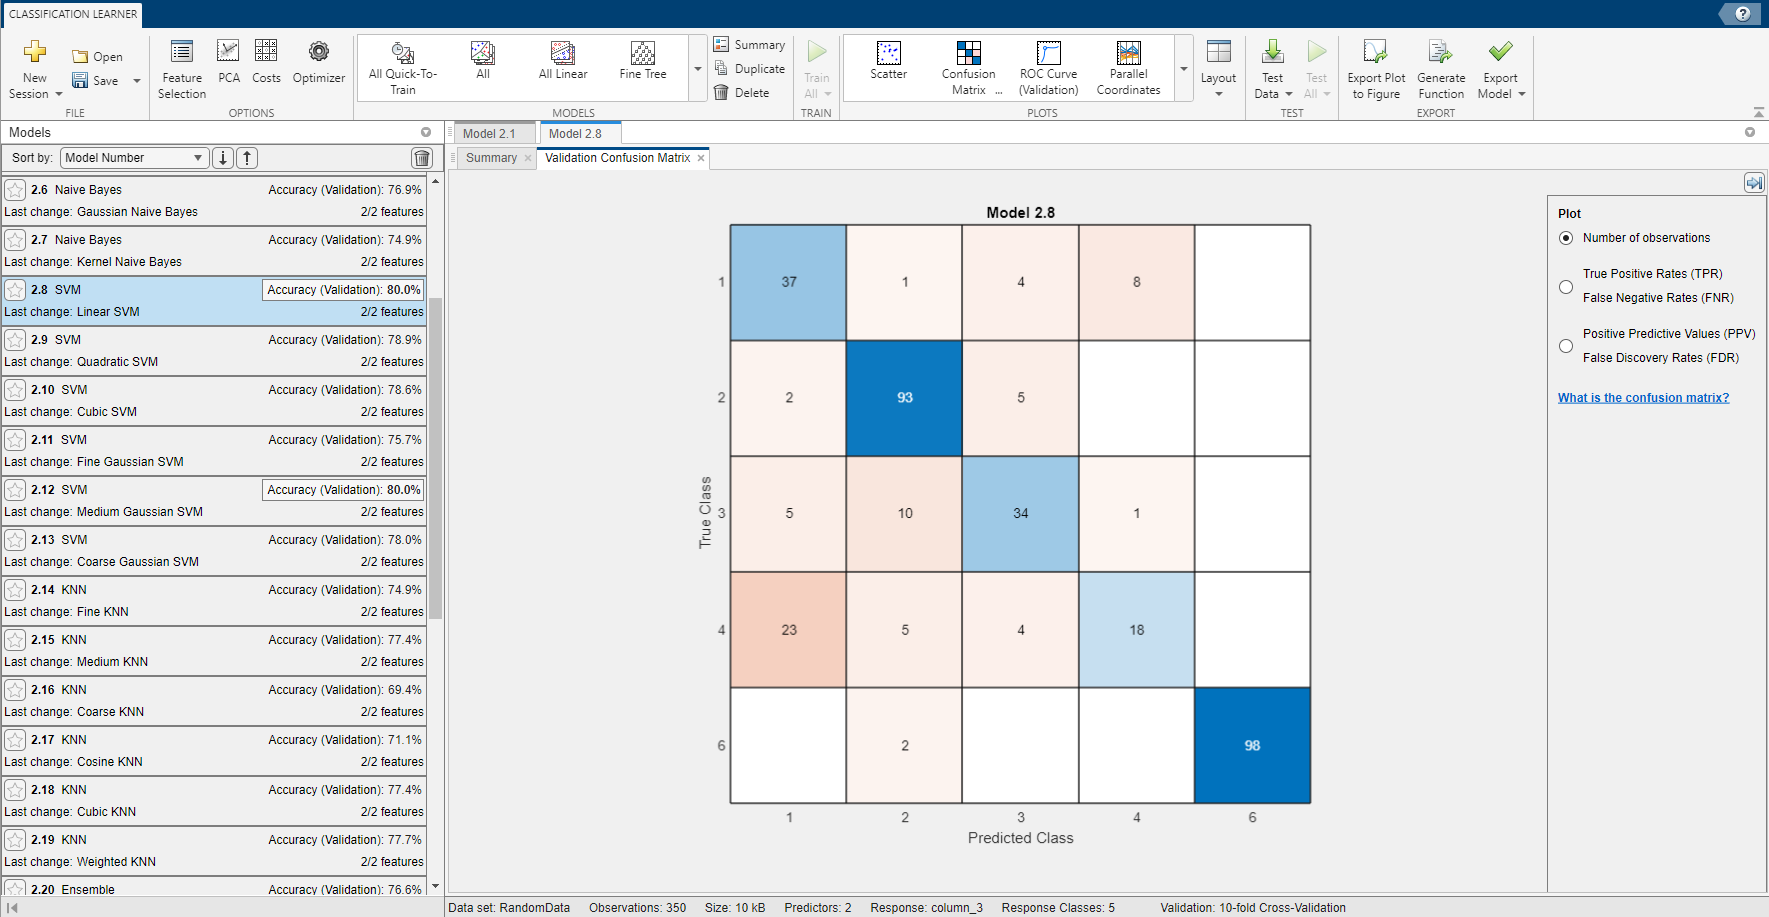

# 3- Validation

[trainedClassifier, validationAccuracy]=trainClassifierLinearSVM(Training);
yfit = trainedClassifier.predictFcn(Validation(:,1:2));
TrueClass=Validation(:,3);
compare= yfit == TrueClass;
aciertos = sum(compare)

aciertos = 90

aciertos/length(compare)

ans = 0.8571